# **Analize Measured Data**

mu_0 = 4*pi*1e-7;                 %Magnetic Permeability of Vacuum

**For Z axis**

IS501NMTB.Z.L = 1.03;
IS501NMTB.Z.a = IS501NMTB.Z.L/2;
IS501NMTB.Z.h = 0.5 ;
IS501NMTB.Z.N = 20;
IS501NMTB.Z.R = 10.32;
IS501NMTB.Z.Lz = IS501NMTB.Z.N^2*(2^(1/2)*mu_0*IS501NMTB.Z.L^2)/(IS501NMTB.Z.a*pi);
IS501NMTB.Z.tau = IS501NMTB.Z.Lz/IS501NMTB.Z.R;

**For Y axis**

IS501NMTB.Y.L = 1.02;
IS501NMTB.Y.a = IS501NMTB.Y.L/2;
IS501NMTB.Y.h = 0.5;
IS501NMTB.Y.N = 35;
IS501NMTB.Y.R = 7.61;
IS501NMTB.Y.Ly = IS501NMTB.Y.N^2*(2^(1/2)*mu_0*IS501NMTB.Y.L^2)/(IS501NMTB.Y.a*pi);
IS501NMTB.Y.tau = IS501NMTB.Y.Ly/IS501NMTB.Y.R;

**For X axis**

IS501NMTB.X.L = 1.03;
IS501NMTB.X.a = IS501NMTB.X.L/2 ;
IS501NMTB.X.h = 0.5;
IS501NMTB.X.N = 36;
IS501NMTB.X.R = 14.84;
IS501NMTB.X.Lx = IS501NMTB.X.N^2*(2^(1/2)*mu_0*IS501NMTB.X.L^2)/(IS501NMTB.X.a*pi);
IS501NMTB.X.tau = IS501NMTB.X.Lx/IS501NMTB.X.R;

## 1. Analize data measured 2/08/2014

%%% Read data measured from previous tests
fileName_x_jhonny = 'data_20210101/A_FUNCION_TRANSFERENCIA_X.mat'; 
fileName_y_jhonny = 'data_20210101/A_FUNCION_TRANSFERENCIA_Y.mat'; 
fileName_z_jhonny = 'data_20210101/A_FUNCION_TRANSFERENCIA_Z.mat';
load(fileName_x_jhonny); load(fileName_y_jhonny); load(fileName_z_jhonny);
jhonny.xcoil = readProcessData_jhonny(TRANSFERENCIA_X,1,-1);
jhonny.ycoil = readProcessData_jhonny(TRANSFERENCIA_Y,1,-1);
jhonny.zcoil = readProcessData_jhonny(TRANSFERENCIA_Z,1,-1);
%%%Clear unused data
clear TRANSFERENCIA_X TRANSFERENCIA_Y TRANSFERENCIA_Z fileName_x_jhonny fileName_y_jhonny fileName_z_jhonny

%%%Perform linear correlation for magnetic field
degree_of_polynomial = 1;
jhonny.coeffsB.x = polyfit(jhonny.xcoil.I, jhonny.xcoil.B , degree_of_polynomial);
jhonny.coeffsB.y = polyfit(jhonny.ycoil.I, jhonny.ycoil.B , degree_of_polynomial);
jhonny.coeffsB.z = polyfit(jhonny.zcoil.I, jhonny.zcoil.B , degree_of_polynomial);

%%%create curves with the measured values
jhonny.fitB.x = polyval(jhonny.coeffsB.x, jhonny.xcoil.I); % Calculate fitted y values
jhonny.ecuacion_regresionB.x = sprintf('y = %.2fx + %.2f',jhonny.coeffsB.x(1), jhonny.coeffsB.x(2));
%%create curves with the measured values
jhonny.fitB.y = polyval(jhonny.coeffsB.y, jhonny.ycoil.I); % Calculate fitted y values
jhonny.ecuacion_regresionB.y = sprintf('y = %.2fx + %.2f',jhonny.coeffsB.y(1), jhonny.coeffsB.y(2));
%%create curves with the measured values
jhonny.fitB.z = polyval(jhonny.coeffsB.z, jhonny.zcoil.I); % Calculate fitted y values
jhonny.ecuacion_regresionB.z = sprintf('y = %.2fx + %.2f',jhonny.coeffsB.z(1), jhonny.coeffsB.z(2));

%%%Perform linear correlation for resistance
degree_of_polynomial = 1;
jhonny.coeffsRes.x = polyfit(jhonny.xcoil.I, jhonny.xcoil.V , degree_of_polynomial);
jhonny.coeffsRes.y = polyfit(jhonny.ycoil.I, jhonny.ycoil.V , degree_of_polynomial);
jhonny.coeffsRes.z = polyfit(jhonny.zcoil.I, jhonny.zcoil.V , degree_of_polynomial);

%%%create curves with the measured values
jhonny.fitRes.x = polyval(jhonny.coeffsRes.x, jhonny.xcoil.I); % Calculate fitted y values
jhonny.ecuacion_regresionRes.x = sprintf('y = %.2fx + %.2f',jhonny.coeffsRes.x(1), jhonny.coeffsRes.x(2));
%%create curves with the measured values
jhonny.fitRes.y = polyval(jhonny.coeffsRes.y, jhonny.ycoil.I); % Calculate fitted y values
jhonny.ecuacion_regresionRes.y = sprintf('y = %.2fx + %.2f',jhonny.coeffsRes.y(1), jhonny.coeffsRes.y(2));
%%create curves with the measured values
jhonny.fitRes.z = polyval(jhonny.coeffsRes.z, jhonny.zcoil.I); % Calculate fitted y values
jhonny.ecuacion_regresionRes.z = sprintf('y = %.2fx + %.2f',jhonny.coeffsRes.z(1), jhonny.coeffsRes.z(2));

clearvars -except jhonny IS501NMTB;

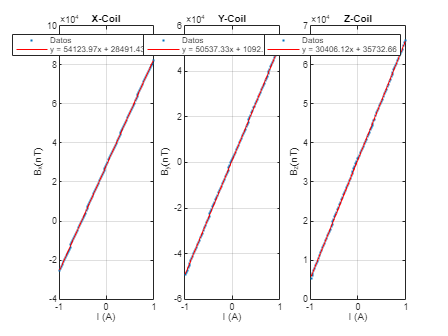

%%%Plot results
figure()
subplot(1,3,1)
    plot(jhonny.xcoil.I,jhonny.xcoil.B,'.'); hold on;
    plot(jhonny.xcoil.I,jhonny.fitB.x,'r-'); legend('Datos', jhonny.ecuacion_regresionB.x);
    xlabel('I (A)'); ylabel('B_x(nT)'); grid on; title('X-Coil');
subplot(1,3,2)
    plot(jhonny.ycoil.I,jhonny.ycoil.B,'.'); hold on;
    plot(jhonny.ycoil.I,jhonny.fitB.y,'r-'); legend('Datos', jhonny.ecuacion_regresionB.y);
    xlabel('I (A)'); ylabel('B_y(nT)'); grid on; title('Y-Coil');
subplot(1,3,3)
    plot(jhonny.zcoil.I,jhonny.zcoil.B,'.'); hold on;
    plot(jhonny.zcoil.I,jhonny.fitB.z,'r-'); legend('Datos', jhonny.ecuacion_regresionB.z);
    xlabel('I (A)'); ylabel('B_z(nT)'); grid on; title('Z-Coil');

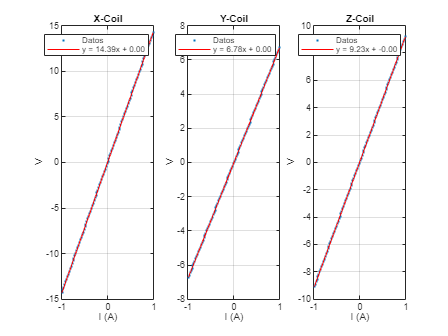

 figure()
subplot(1,3,1)
    plot(jhonny.xcoil.I,jhonny.xcoil.V,'.'); hold on;
    plot(jhonny.xcoil.I,jhonny.fitRes.x,'r-'); legend('Datos', jhonny.ecuacion_regresionRes.x);
    xlabel('I (A)'); ylabel('V'); grid on; title('X-Coil');
subplot(1,3,2)
    plot(jhonny.ycoil.I,jhonny.ycoil.V,'.'); hold on;
    plot(jhonny.ycoil.I,jhonny.fitRes.y,'r-'); legend('Datos', jhonny.ecuacion_regresionRes.y);
    xlabel('I (A)'); ylabel('V'); grid on; title('Y-Coil');
subplot(1,3,3)
    plot(jhonny.zcoil.I,jhonny.zcoil.V,'.'); hold on;
    plot(jhonny.zcoil.I,jhonny.fitRes.z,'r-'); legend('Datos', jhonny.ecuacion_regresionRes.z);
    xlabel('I (A)'); ylabel('V'); grid on; title('Z-Coil');

    clearvars -except IS501NMTB xcoil ycoil zcoil jhonny

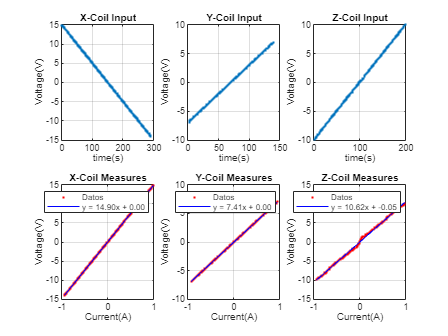

%%% Read data measured from previous tests
fileName_x = 'data_20240114/xCoil_Epoch_2024_01_14.mat'; 
fileName_y = 'data_20240114/yCoil_Epoch_2024_01_14.mat'; 
fileName_z = 'data_20240114/zCoil_Epoch_2024_01_14.mat';
load(fileName_x); load(fileName_y); load(fileName_z);

%%% Interpretate and Clean Data
measuredData.xcoil = readProcessData(x_coil_data);
measuredData.ycoil = readProcessData(y_coil_data);
measuredData.zcoil = readProcessData(z_coil_data);

%%%Clear unused data
clear x_coil_data y_coil_data z_coil_data fileName_x fileName_y fileName_z

%%%Perform linear regression of degree 1 (a straight line)
degree_of_polynomial = 1;
coeffs_x = polyfit(measuredData.xcoil.I, measuredData.xcoil.V , degree_of_polynomial);
coeffs_y = polyfit(measuredData.ycoil.I, measuredData.ycoil.V , degree_of_polynomial);
coeffs_z = polyfit(measuredData.zcoil.I, measuredData.zcoil.V , degree_of_polynomial);

%%create curves with the measured values
y_fit_x = polyval(coeffs_x, measuredData.xcoil.I); % Calculate fitted y values
ecuacion_regresion_x = sprintf('y = %.2fx + %.2f',coeffs_x(1), coeffs_x(2));
%%create curves with the measured values
y_fit_y = polyval(coeffs_y, measuredData.ycoil.I); % Calculate fitted y values
ecuacion_regresion_y = sprintf('y = %.2fx + %.2f',coeffs_y(1), coeffs_y(2));
%%create curves with the measured values
y_fit_z = polyval(coeffs_z, measuredData.zcoil.I); % Calculate fitted y values
ecuacion_regresion_z = sprintf('y = %.2fx + %.2f',coeffs_z(1), coeffs_z(2));

%%%Plot the data and the linear regression line
figure()
subplot(2,3,1)
    plot(measuredData.xcoil.time,measuredData.xcoil.V,'.','LineWidth',3);hold on;
    xlabel('time(s)'); ylabel('Voltage(V)'); grid on; title('X-Coil Input');
subplot(2,3,2)
    plot(measuredData.ycoil.time,measuredData.ycoil.V,'.','LineWidth',3);hold on;
    xlabel('time(s)'); ylabel('Voltage(V)'); grid on; title('Y-Coil Input');
subplot(2,3,3)
    plot(measuredData.zcoil.time,measuredData.zcoil.V,'.','LineWidth',3);hold on;
    xlabel('time(s)'); ylabel('Voltage(V)'); grid on; title('Z-Coil Input');
    
subplot(2,3,4)
    plot(measuredData.xcoil.I, measuredData.xcoil.V,'r.','LineWidth',3);hold on;
    plot(measuredData.xcoil.I, y_fit_x, 'b-');
    ylabel('Voltage(V)'); xlabel('Current(A)'); grid on; title('X-Coil Measures')
    legend('Datos', ecuacion_regresion_x);
subplot(2,3,5)
    plot(measuredData.ycoil.I, measuredData.ycoil.V,'r.','LineWidth',3);hold on;
    plot(measuredData.ycoil.I, y_fit_y, 'b-');
    ylabel('Voltage(V)'); xlabel('Current(A)'); grid on; title('Y-Coil Measures')
    legend('Datos', ecuacion_regresion_y);
subplot(2,3,6)
    plot(measuredData.zcoil.I, measuredData.zcoil.V,'r.','LineWidth',3);hold on;
    plot(measuredData.zcoil.I, y_fit_z, 'b-');
    ylabel('Voltage(V)'); xlabel('Current(A)'); grid on; title('Z-Coil Measures')
    legend('Datos', ecuacion_regresion_z);

Compare data of 2021 and 2024

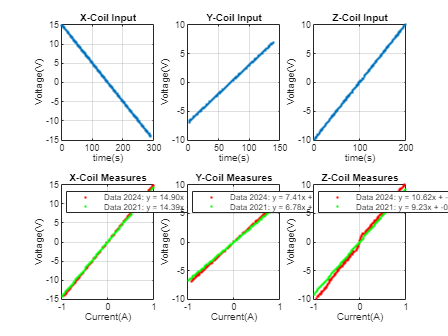

    %%%Plot the data and the linear regression line
figure()
subplot(2,3,1)
    plot(measuredData.xcoil.time,measuredData.xcoil.V,'.','LineWidth',3);hold on;
    xlabel('time(s)'); ylabel('Voltage(V)'); grid on; title('X-Coil Input');
subplot(2,3,2)
    plot(measuredData.ycoil.time,measuredData.ycoil.V,'.','LineWidth',3);hold on;
    xlabel('time(s)'); ylabel('Voltage(V)'); grid on; title('Y-Coil Input');
subplot(2,3,3)
    plot(measuredData.zcoil.time,measuredData.zcoil.V,'.','LineWidth',3);hold on;
    xlabel('time(s)'); ylabel('Voltage(V)'); grid on; title('Z-Coil Input');
    
subplot(2,3,4)
    plot(measuredData.xcoil.I, measuredData.xcoil.V,'r.','LineWidth',3);hold on;
    plot(jhonny.xcoil.I,jhonny.xcoil.V,'g.'); 
    %plot(measuredData.xcoil.I, y_fit_x, 'b--');
    ylabel('Voltage(V)'); xlabel('Current(A)'); grid on; title('X-Coil Measures')
    %legend('Data 2024','Data 2021', ecuacion_regresion_x);
    legend(['Data 2024: ', ecuacion_regresion_x],['Data 2021: ', jhonny.ecuacion_regresionRes.x],'Location','northwest');
subplot(2,3,5)
    plot(measuredData.ycoil.I, measuredData.ycoil.V,'r.','LineWidth',3);hold on;
    plot(jhonny.ycoil.I,jhonny.ycoil.V,'g.'); 
    %plot(measuredData.ycoil.I, y_fit_y, 'b--');
    ylabel('Voltage(V)'); xlabel('Current(A)'); grid on; title('Y-Coil Measures')
    legend(['Data 2024: ', ecuacion_regresion_y],['Data 2021: ', jhonny.ecuacion_regresionRes.y],'Location','northwest');
    %legend('Data 2024','Data 2021', ecuacion_regresion_y);
subplot(2,3,6)
    plot(measuredData.zcoil.I, measuredData.zcoil.V,'r.','LineWidth',3);hold on;
    plot(jhonny.zcoil.I,jhonny.zcoil.V,'g.'); 
    %plot(measuredData.zcoil.I, y_fit_z, 'b--');
    ylabel('Voltage(V)'); xlabel('Current(A)'); grid on; title('Z-Coil Measures')
    legend(['Data 2024: ', ecuacion_regresion_z],['Data 2021: ', jhonny.ecuacion_regresionRes.z],'Location','northwest');

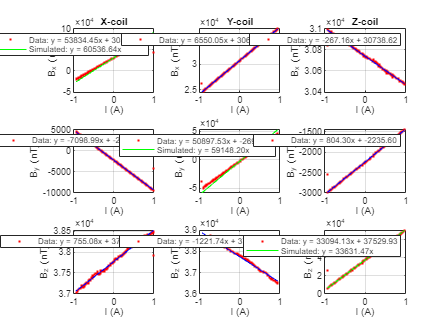

%%%Perform linear regression of degree 1 (a straight line)
degree_of_polynomial = 1;
%%%Linear regresion1
coeffs_x1 = polyfit(measuredData.xcoil.I, measuredData.xcoil.Bx , degree_of_polynomial);
coeffs_x2 = polyfit(measuredData.xcoil.I, measuredData.xcoil.By , degree_of_polynomial);
coeffs_x3 = polyfit(measuredData.xcoil.I, measuredData.xcoil.Bz , degree_of_polynomial);
%%%Linear regresion2
coeffs_y1 = polyfit(measuredData.ycoil.I, measuredData.ycoil.Bx , degree_of_polynomial);
coeffs_y2 = polyfit(measuredData.ycoil.I, measuredData.ycoil.By , degree_of_polynomial);
coeffs_y3 = polyfit(measuredData.ycoil.I, measuredData.ycoil.Bz , degree_of_polynomial);
%%%Linear regresion2
coeffs_z1 = polyfit(measuredData.zcoil.I, measuredData.zcoil.Bx , degree_of_polynomial);
coeffs_z2 = polyfit(measuredData.zcoil.I, measuredData.zcoil.By , degree_of_polynomial);
coeffs_z3 = polyfit(measuredData.zcoil.I, measuredData.zcoil.Bz , degree_of_polynomial);

%%%Create curves
%%create curves with the measured values
xcoil_fit_x = polyval(coeffs_x1, measuredData.xcoil.I); 
xcoil_regresion_x = sprintf('y = %.2fx + %.2f',coeffs_x1(1), coeffs_x1(2));
%%create curves with the measured values
xcoil_fit_y = polyval(coeffs_x2, measuredData.xcoil.I); 
xcoil_regresion_y = sprintf('y = %.2fx + %.2f',coeffs_x2(1), coeffs_x2(2));
%%create curves with the measured values
xcoil_fit_z = polyval(coeffs_x3, measuredData.xcoil.I); 
xcoil_regresion_z = sprintf('y = %.2fx + %.2f',coeffs_x3(1), coeffs_x3(2));

%%%Create curves
%%create curves with the measured values
ycoil_fit_x = polyval(coeffs_y1, measuredData.ycoil.I); 
ycoil_regresion_x = sprintf('y = %.2fx + %.2f',coeffs_y1(1), coeffs_y1(2));
%%create curves with the measured values
ycoil_fit_y = polyval(coeffs_y2, measuredData.ycoil.I); 
ycoil_regresion_y = sprintf('y = %.2fx + %.2f',coeffs_y2(1), coeffs_y2(2));
%%create curves with the measured values
ycoil_fit_z = polyval(coeffs_y3, measuredData.ycoil.I); 
ycoil_regresion_z = sprintf('y = %.2fx + %.2f',coeffs_y3(1), coeffs_y3(2));

%%%Create curves
%%create curves with the measured values
zcoil_fit_x = polyval(coeffs_z1, measuredData.zcoil.I); 
zcoil_regresion_x = sprintf('y = %.2fx + %.2f',coeffs_z1(1), coeffs_z1(2));
%%create curves with the measured values
zcoil_fit_y = polyval(coeffs_z2, measuredData.zcoil.I); 
zcoil_regresion_y = sprintf('y = %.2fx + %.2f',coeffs_z2(1), coeffs_z2(2));
%%create curves with the measured values
zcoil_fit_z = polyval(coeffs_z3, measuredData.zcoil.I); 
zcoil_regresion_z = sprintf('y = %.2fx + %.2f',coeffs_z3(1), coeffs_z3(2));

%%%Simulated data 
%%%Biot Savart law at x=0
mu_0 = 4*pi*1e-7;    % Permeability in the vacum
functBxyz0 = @(N,I,a,h) (4 * mu_0 * N *I * a^2) / (pi) * (1/((a^2 + (h/2)^2) * (2 * a^2 + (h/2)^2)^(1/2)));
coeff_teor = @(N,a,h) (4 * mu_0 * N * a^2) / (pi) * (1/((a^2 + (h/2)^2) * (2 * a^2 + (h/2)^2)^(1/2)));
calcN = @(a,h) (4 * mu_0 * a^2) / (pi) * (1/((a^2 + (h/2)^2) * (2 * a^2 + (h/2)^2)^(1/2)));

expN.x = (abs(coeffs_x1(1))+abs(coeffs_x2(1))+abs(coeffs_x3(1)))/(calcN(IS501NMTB.X.a,IS501NMTB.X.h)*1E9);
expN.y = (abs(coeffs_y1(1))+abs(coeffs_y2(1))+abs(coeffs_y3(1)))/(calcN(IS501NMTB.Y.a,IS501NMTB.Y.h)*1E9);
expN.z = (abs(coeffs_z1(1))+abs(coeffs_z2(1))+abs(coeffs_z3(1)))/(calcN(IS501NMTB.Z.a,IS501NMTB.Z.h)*1E9);

simulated.coeff.B_x = coeff_teor(IS501NMTB.X.N,IS501NMTB.X.a, IS501NMTB.X.h)*1E9;
simulated.coeff.B_y = coeff_teor(IS501NMTB.Y.N,IS501NMTB.Y.a, IS501NMTB.Y.h)*1E9;
simulated.coeff.B_z = coeff_teor(IS501NMTB.Z.N,IS501NMTB.Z.a, IS501NMTB.Z.h)*1E9;
xcoil_teo_regresion_x = sprintf('y = %.2fx',simulated.coeff.B_x);
ycoil_teo_regresion_y = sprintf('y = %.2fx',simulated.coeff.B_y);
zcoil_teo_regresion_z = sprintf('y = %.2fx',simulated.coeff.B_z);

simulated.B_x = functBxyz0(IS501NMTB.X.N, measuredData.xcoil.I, IS501NMTB.X.a, IS501NMTB.X.h)*1E9; %% In (nT)
simulated.B_y = functBxyz0(IS501NMTB.Y.N, measuredData.ycoil.I, IS501NMTB.Y.a, IS501NMTB.Y.h)*1E9; %% In (nT)
simulated.B_z = functBxyz0(IS501NMTB.Z.N, measuredData.zcoil.I, IS501NMTB.Z.a, IS501NMTB.Z.h)*1E9; %% In (nT)

errorx = (abs(coeffs_x1(1)-simulated.coeff.B_x)/coeffs_x1(1))*100;
errory = (abs(coeffs_y2(1)-simulated.coeff.B_y)/coeffs_y2(1))*100;
errorz = (abs(coeffs_z3(1)-simulated.coeff.B_z)/coeffs_z3(1))*100;

%%%Plot results
figure()
    subplot(3,3,1)
        plot(measuredData.xcoil.I,measuredData.xcoil.Bx,'r.'); hold on; grid on;
        %plot(measuredData.xcoil.I, xcoil_fit_x, 'b-');
        plot(measuredData.xcoil.I, simulated.B_x+coeffs_x1(2),'g'),
        title('X-coil'); legend(['Data: ', xcoil_regresion_x], ['Simulated: ',xcoil_teo_regresion_x]);
        xlabel('I (A)'); ylabel('B_x (nT)');
    subplot(3,3,2)
        h1 = plot(measuredData.ycoil.I,measuredData.ycoil.Bx,'r.'); hold on; grid on;
        plot(measuredData.ycoil.I, ycoil_fit_x, 'b-');
        title('Y-coil'); legend(h1,['Data: ', ycoil_regresion_x]);
        xlabel('I (A)'); ylabel('B_x (nT)');
    subplot(3,3,3)
        h1 = plot(measuredData.zcoil.I,measuredData.zcoil.Bx,'r.'); hold on; grid on;
        plot(measuredData.zcoil.I, zcoil_fit_x, 'b-');
        title('Z-coil'); legend(h1,['Data: ', zcoil_regresion_x]);
        xlabel('I (A)'); ylabel('B_x (nT)');
        
    subplot(3,3,4)
        h1 = plot(measuredData.xcoil.I,measuredData.xcoil.By,'r.'); hold on; grid on;
        plot(measuredData.xcoil.I, xcoil_fit_y, 'b-');
        xlabel('I (A)'); ylabel('B_y (nT)'); legend(h1,['Data: ', xcoil_regresion_y]);
    subplot(3,3,5)
        plot(measuredData.ycoil.I,measuredData.ycoil.By,'r.'); hold on; grid on;
        %plot(measuredData.ycoil.I, ycoil_fit_y, 'b-');
        plot(measuredData.ycoil.I, simulated.B_y+coeffs_y2(2),'g'),
        xlabel('I (A)'); ylabel('B_y (nT)'); 
        legend(['Data: ', ycoil_regresion_y],['Simulated: ',ycoil_teo_regresion_y]);
    subplot(3,3,6)
        h1 = plot(measuredData.zcoil.I,measuredData.zcoil.By,'r.'); hold on; grid on;
        plot(measuredData.zcoil.I, zcoil_fit_y, 'b-');
        xlabel('I (A)'); ylabel('B_y (nT)'); legend(h1,['Data: ', zcoil_regresion_y]);

    subplot(3,3,7)
        h2 = plot(measuredData.xcoil.I,measuredData.xcoil.Bz,'r.'); hold on; grid on;
        plot(measuredData.xcoil.I, xcoil_fit_z, 'b-');
        xlabel('I (A)'); ylabel('B_z (nT)'); legend(h2,['Data: ', xcoil_regresion_z]);
    subplot(3,3,8)
        h1 = plot(measuredData.ycoil.I,measuredData.ycoil.Bz,'r.'); hold on; grid on;
        plot(measuredData.ycoil.I, ycoil_fit_z, 'b-');
        xlabel('I (A)'); ylabel('B_z (nT)'); legend(h1,['Data: ', ycoil_regresion_z]);
    subplot(3,3,9)
        plot(measuredData.zcoil.I,measuredData.zcoil.Bz,'r.'); hold on; grid on;
        %plot(measuredData.zcoil.I, zcoil_fit_z, 'b-');
        plot(measuredData.zcoil.I, simulated.B_z+coeffs_z3(2),'g'),
        xlabel('I (A)'); ylabel('B_z (nT)'); 
        legend(['Data: ', zcoil_regresion_z],['Simulated: ',zcoil_teo_regresion_z]);

Compare data from 2021 and 2024

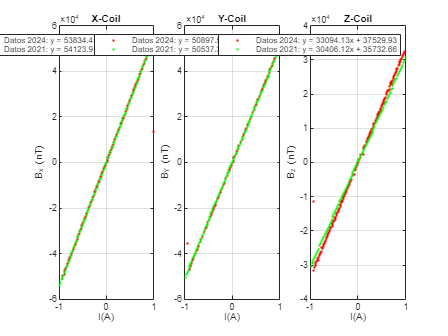

%%%Plot the data and the linear regression line
figure()
subplot(1,3,1)
    plot(measuredData.xcoil.I,measuredData.xcoil.Bx-coeffs_x1(2),'r.'); hold on; grid on;
    plot(jhonny.xcoil.I,jhonny.xcoil.B-jhonny.coeffsB.x(2),'g.');
    xlabel('I(A)'); ylabel('B_x (nT)'); grid on; title('X-Coil');
    legend(['Datos 2024: ', xcoil_regresion_x],['Datos 2021: ', jhonny.ecuacion_regresionB.x])
subplot(1,3,2)
    plot(measuredData.ycoil.I,measuredData.ycoil.By-coeffs_y2(2),'r.'); hold on; grid on;
    plot(jhonny.ycoil.I,jhonny.ycoil.B-jhonny.coeffsB.y(2),'g.');
    xlabel('I(A)'); ylabel('B_Y (nT)'); grid on; title('Y-Coil');
    legend(['Datos 2024: ', ycoil_regresion_y],['Datos 2021: ', jhonny.ecuacion_regresionB.y])
subplot(1,3,3)
    plot(measuredData.zcoil.I,measuredData.zcoil.Bz-coeffs_z3(2),'r.'); hold on; grid on;
    plot(jhonny.zcoil.I,jhonny.zcoil.B-jhonny.coeffsB.z(2),'g.');
    xlabel('I(A)'); ylabel('B_z (nT)'); grid on; title('Z-Coil');
    legend(['Datos 2024: ', zcoil_regresion_z],['Datos 2021: ', jhonny.ecuacion_regresionB.z]);

**System identification**

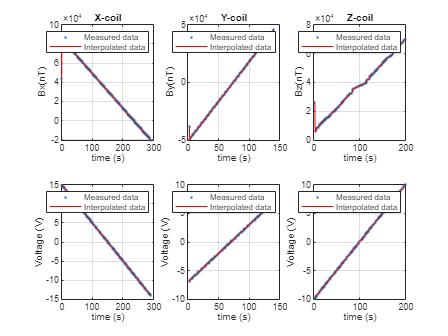

[identification.xcoil.t, identification.xcoil.B] = setSampleTime(measuredData.xcoil.time,measuredData.xcoil.Bx,0.2);
[identification.xcoil.t, identification.xcoil.V] = setSampleTime(measuredData.xcoil.time,measuredData.xcoil.V ,0.2);
[identification.ycoil.t, identification.ycoil.B] = setSampleTime(measuredData.ycoil.time,measuredData.ycoil.By,0.2);
[identification.ycoil.t, identification.ycoil.V] = setSampleTime(measuredData.ycoil.time,measuredData.ycoil.V ,0.2);
[identification.zcoil.t, identification.zcoil.B] = setSampleTime(measuredData.zcoil.time,measuredData.zcoil.Bz,0.2);
[identification.zcoil.t, identification.zcoil.V] = setSampleTime(measuredData.zcoil.time,measuredData.zcoil.V ,0.2);

figure()
subplot(2,3,1)
    h9  = plot(measuredData.xcoil.time,measuredData.xcoil.Bx,'.'); hold on;
    h10 = plot(identification.xcoil.t, identification.xcoil.B,'r-');
    legend([h9,h10],'Measured data','Interpolated data'); title('X-coil');
    xlabel('time (s)'); ylabel('Bx(nT)');grid on;
subplot(2,3,2)
    h9  = plot(measuredData.ycoil.time,measuredData.ycoil.By,'.'); hold on;
    h10 = plot(identification.ycoil.t, identification.ycoil.B,'r-');
    legend([h9,h10],'Measured data','Interpolated data'); title('Y-coil');
    xlabel('time (s)'); ylabel('By(nT)');grid on;
subplot(2,3,3)
    h9  = plot(measuredData.zcoil.time,measuredData.zcoil.Bz,'.'); hold on;
    h10 = plot(identification.zcoil.t, identification.zcoil.B,'r-');
    legend([h9,h10],'Measured data','Interpolated data'); title('Z-coil');
    xlabel('time (s)'); ylabel('Bz(nT)');grid on;
subplot(2,3,4)
    h9  = plot(measuredData.xcoil.time,measuredData.xcoil.V,'.'); hold on;
    h10 = plot(identification.xcoil.t, identification.xcoil.V,'r-');
    legend([h9,h10],'Measured data','Interpolated data'); %title('X-coil');
    xlabel('time (s)'); ylabel('Voltage (V)');grid on;
subplot(2,3,5)
    h9  = plot(measuredData.ycoil.time,measuredData.ycoil.V,'.'); hold on;
    h10 = plot(identification.ycoil.t, identification.ycoil.V,'r-');
    legend([h9,h10],'Measured data','Interpolated data'); %title('Y-coil');
    xlabel('time (s)'); ylabel('Voltage (V)');grid on;
subplot(2,3,6)
    h9  = plot(measuredData.zcoil.time,measuredData.zcoil.V,'.'); hold on;
    h10 = plot(identification.zcoil.t, identification.zcoil.V,'r-');
    legend([h9,h10],'Measured data','Interpolated data'); %title('Z-coil');
    xlabel('time (s)'); ylabel('Voltage (V)');grid on;

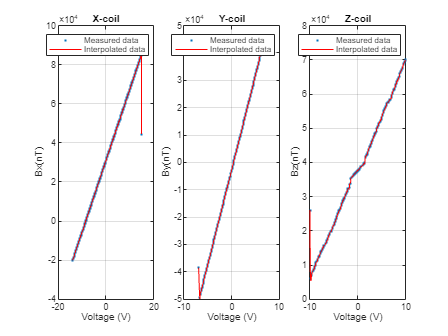

figure()
subplot(1,3,1)
    h9  = plot(measuredData.xcoil.V,measuredData.xcoil.Bx,'.'); hold on;
    h10 = plot(identification.xcoil.V, identification.xcoil.B,'r-');
    legend([h9,h10],'Measured data','Interpolated data'); title('X-coil');
    xlabel('Voltage (V)'); ylabel('Bx(nT)');grid on;
subplot(1,3,2)
    h9  = plot(measuredData.ycoil.V,measuredData.ycoil.By,'.'); hold on;
    h10 = plot(identification.ycoil.V, identification.ycoil.B,'r-');
    legend([h9,h10],'Measured data','Interpolated data'); title('Y-coil');
    xlabel('Voltage (V)'); ylabel('By(nT)');grid on;
subplot(1,3,3)
    h9  = plot(measuredData.zcoil.V,measuredData.zcoil.Bz,'.'); hold on;
    h10 = plot(identification.zcoil.V, identification.zcoil.B,'r-');
    legend([h9,h10],'Measured data','Interpolated data'); title('Z-coil');
    xlabel('Voltage (V)'); ylabel('Bz(nT)');grid on;

## **3. Analize Disturbances Data**

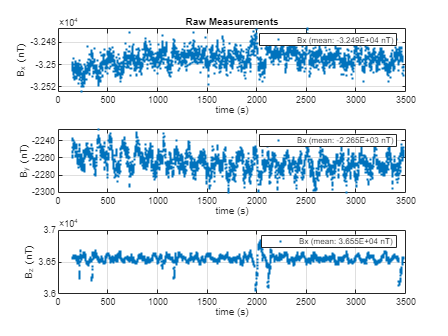

%%%Add raw data from magnetometer
load('staticMagData_Epoch_2024_01_04.mat');
%%%Interpretate Data
time = staticDataStore(1,925:end-1);
Bx = staticDataStore(2,925:end-1); By = staticDataStore(3,925:end-1); Bz = staticDataStore(4,925:end-1);
%%Remove NAN values
staticMeasures.time = time(~isnan(time));
staticMeasures.Bx   = Bx(~isnan(Bx));
staticMeasures.By   = By(~isnan(By));
staticMeasures.Bz   = Bz(~isnan(Bz));
%%Clear unused data
clear Bx By Bz time staticDataStore;

%%%Recover data with coils off
figure()
%%%Get mean values
Bxreal_mean = mean(staticMeasures.Bx);
Byreal_mean = mean(staticMeasures.By);
Bzreal_mean = mean(staticMeasures.Bz);

subplot(3,1,1)
    h1 = plot(staticMeasures.time, staticMeasures.Bx,'.'); grid on;
    title('Raw Measurements'); legend(h1, ['Bx (mean: ',num2str(Bxreal_mean,'%.3E'),' nT)']);
    xlabel('time (s)'); ylabel('B_x (nT)'); 

subplot(3,1,2)
    h2 = plot(staticMeasures.time, staticMeasures.By,'.'); grid on;
    legend(h2, ['Bx (mean: ',num2str(Byreal_mean,'%.3E'),' nT)']);
    xlabel('time (s)'); ylabel('B_y (nT)'); 

subplot(3,1,3)
    h3 = plot(staticMeasures.time, staticMeasures.Bz,'.'); grid on;
    legend(h3, ['Bx (mean: ',num2str(Bzreal_mean,'%.3E'),' nT)']);
    xlabel('time (s)'); ylabel('B_z (nT)');   

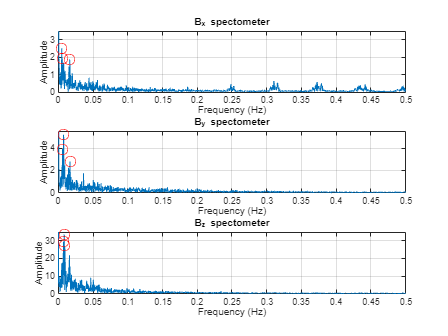

figure()
subplot(3,1,1)
    [gx, top_three_pks_Bx, top_three_freq_Bx, constant_Bx, t_uniform_Bx, x_uniform_Bx] = fftAalisys(staticMeasures.time,staticMeasures.Bx);
    title('B_x spectometer'); xlim([0 0.5]); ylim([0 3.5]);
subplot(3,1,2)
    [gy, top_three_pks_By, top_three_freq_By, constant_By, t_uniform_By, x_uniform_By] = fftAalisys(staticMeasures.time,staticMeasures.By);
    title('B_y spectometer'); xlim([0 0.5]); ylim([0 5.5]);
subplot(3,1,3)
    [gz, top_three_pks_Bz, top_three_freq_Bz, constant_Bz, t_uniform_Bz, x_uniform_Bz] = fftAalisys(staticMeasures.time,staticMeasures.Bz);
    title('B_z spectometer'); xlim([0 0.5]); ylim([0 35]);

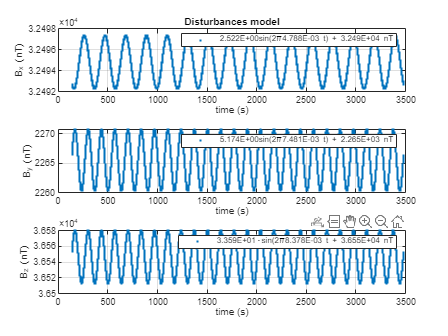

%%%Calculate disturbances model for the Heltholtz cage
    x_disturbances = constant_Bx + top_three_pks_Bx(1)*sin(2*pi*top_three_freq_Bx(1)*t_uniform_Bx);
    y_disturbances = constant_By + top_three_pks_By(1)*sin(2*pi*top_three_freq_By(1)*t_uniform_Bz);
    z_disturbances = constant_Bz + top_three_pks_Bz(1)*sin(2*pi*top_three_freq_By(1)*t_uniform_Bz);

%%%Plot disturbances
   figure()
   subplot(3,1,1)
    h1 = plot(t_uniform_Bx, x_disturbances,'.'); grid on;
    title('Disturbances model'); 
    legend(h1, [num2str(top_three_pks_Bx(1),'%.3E') 'sin(2\pi',num2str(top_three_freq_Bx(1),'%.3E'),' t) + ', num2str(constant_Bx,'%.3E'), ' nT']);
    xlabel('time (s)'); ylabel('B_x (nT)'); 

subplot(3,1,2)
    h2 = plot(t_uniform_By, y_disturbances,'.'); grid on;
    legend(h2, [num2str(top_three_pks_By(1),'%.3E') 'sin(2\pi',num2str(top_three_freq_By(1),'%.3E'),' t) + ', num2str(constant_By,'%.3E'), ' nT']);
    xlabel('time (s)'); ylabel('B_y (nT)'); 

subplot(3,1,3)
    h3 = plot(t_uniform_Bz, z_disturbances,'.'); grid on;
    legend(h3, [num2str(top_three_pks_Bz(1),'%.3E') '\cdotsin(2\pi',num2str(top_three_freq_Bz(1),'%.3E'),' t + ', num2str(constant_Bz,'%.3E'), ' nT']);
    xlabel('time (s)'); ylabel('B_z (nT)'); 

Compare design disturbances with the real disturbances.

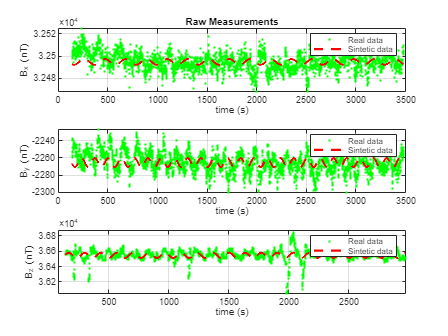

figure() 
subplot(3,1,1)
    h1 = plot(staticMeasures.time, -1*staticMeasures.Bx,'g.'); hold on; grid on;
    h2 = plot(t_uniform_Bx, x_disturbances,'r--','LineWidth',2);
    title('Raw Measurements');
    legend([h1, h2], 'Real data','Sintetic data');
    xlabel('time (s)'); ylabel('B_x (nT)'); 

subplot(3,1,2)
    h3 = plot(staticMeasures.time, staticMeasures.By,'g.'); hold on; grid on;
    h4 = plot(t_uniform_Bx, -1*y_disturbances,'r--','LineWidth',2);
    legend([h3, h4], 'Real data','Sintetic data');
    xlabel('time (s)'); ylabel('B_y (nT)'); 

subplot(3,1,3)
    h5 = plot(staticMeasures.time, staticMeasures.Bz,'g.'); hold on; grid on;
    h6 = plot(t_uniform_Bx, z_disturbances,'r--','LineWidth',2);
    legend([h5, h6], 'Real data','Sintetic data');
    xlabel('time (s)'); ylabel('B_z (nT)');   

function coil = readProcessData(coil_data)
    %%%Interpretate data
    time = coil_data(1,:); Bx = coil_data(2,:); 
    By   = coil_data(3,:); Bz = coil_data(4,:);
    V    = coil_data(5,:); I  = coil_data(6,:);
    %%%Clean data
    coil.time = time(~isnan(time));
    coil.Bx = Bx(~isnan(Bx)); 
    coil.By = By(~isnan(By)); 
    coil.Bz = Bz(~isnan(Bz));
    coil.V  = V(~isnan(V)); 
    coil.I  = I(~isnan(I));
end

function coil = readProcessData_jhonny(coil_data,upLimit, downLimit)
    %%%Interpretate data
    V = coil_data(:,1); I = coil_data(:,2); 
    B = coil_data(:,3);

    %%%Clean data
    coil.V  = V(~isnan(V));
    coil.I  = I(~isnan(I)); 
    coil.B  = B(~isnan(B)); 

    %%%Assign sign to I
    coil.I = sign(coil.V).*coil.I;
    %%%Get the range between lower and upper
    coil.V = coil.V(find(downLimit <= coil.I & upLimit >= coil.I));
    coil.B = coil.B(find(downLimit <= coil.I & upLimit >= coil.I));
    coil.I = coil.I(find(downLimit <= coil.I & upLimit >= coil.I));
end

function [ t_uniform, x_uniform] = setSampleTime(tout,data,t_sample)
    %%% Interpolation to have uniform sampling
    %temp = diff(tout);               %%Temporal time
    %t_sample = mean(temp(1:end-1));                             %%Get sample time
    t_uniform = tout(1):t_sample:tout(end); %%Define a uniform time vector
    %%% Start interpolation
    x_uniform = interp1(tout, data, t_uniform, 'spline');  % Interpolación
end

function [grafica, top_three_pks, top_three_freq, constant, t_uniform, x_uniform] = fftAalisys(tout,data)
    %%% Interpolation to have uniform sampling
    temp = diff(tout);               %%Temporal time
    t_sample = mean(temp(1:end-1));                             %%Get sample time
    t_uniform = tout(1):t_sample:tout(end); %%Define a uniform time vector
    %%% Start interpolation
    x_uniform = interp1(tout, data, t_uniform, 'spline');  % Interpolación
     
    % Calcular la FFT de la señal uniforme
    Fs = 1 / (t_uniform(2) - t_uniform(1));  % Frecuencia de muestreo
    L = length(x_uniform);  % Longitud de la señal
    Y = fft(x_uniform);
    P2 = abs(Y/L);
    P1 = P2(1:L/2+1);
    P1(2:end-1) = 2*P1(2:end-1);
    f = Fs*(0:(L/2))/L;
     
    % Encontrar los picos
    [pks, locs] = findpeaks(P1);
    % Ordenar los picos en orden descendente por valor
    [sorted_pks, sorted_idx] = sort(pks, 'descend');
    % Seleccionar los tres valores más altos
    top_three_pks = sorted_pks(1:3);
    top_three_locs = locs(sorted_idx(1:3));
    top_three_freq = f(top_three_locs);
    
    %Add constant component
    constant = P1(1);
    
    % Graficar la FFT
    plot(f, P1); hold on;
    plot(top_three_freq, top_three_pks, 'ro', 'MarkerSize', 10);  % Marcadores rojos en los picos
    %title('GWSAT-1 Total Disturbance FFT');
    xlabel('Frequency (Hz)');
    ylabel('Amplitude');
    grid on;
    
    % Devuelves el objeto de la gráfica
    grafica = gcf;
end

## **Bibliography**

[1]Uscategui, Jhonny, et al. "High-Precision Magnetic Testbed Design and Simulation for LEO Small-Satellite Control Test." *Aerospace* 10.7 (2023): 640.

[2]Chaisakulsurin, Jormpon, et al. "Hardware-in-the-Loop Simulation Testbed for Three-Axis Earth's Magnetic Field Generation Based on 2.4-Meter Square Helmholtz Coils." *2023 IEEE/ION Position, Location and Navigation Symposium (PLANS)*. IEEE, 2023.

[3]Al-Abri, Aaisha Rashid, et al. "Helmholtz cage for attitude testing of cubesat." *2022 Advances in Science and Engineering Technology International Conferences (ASET)*. IEEE, 2022.

[4] Restrepo, Andrés F., Edinson Franco, and Carlos R. Pinedo. "Metodología de diseño e implementación de un sistema para generación de campos magnéticos uniformes con bobinas Helmholtz Cuadrada Tri-Axial." *Información tecnológica* 25.2 (2014): 03-14.

[5]Martínez, E. "Bobinas de Helmholtz." *Mexico, México DF* (2015).

[6] [Espira Cuadrada Ley de Biot-Savart I - YouTube](https://www.youtube.com/watch?v=IvfkEk6_vks&ab_channel=Dem%C3%B3critoPit%C3%A1goras)

[7]Lapucci, Tommaso, et al. "Soft and Hard Iron Compensation for the Compasses of an Operational Towed Hydrophone Array without Sensor Motion by a Helmholtz Coil." *Sensors* 21.23 (2021): 8104.

[8][Magnetometer Calibration - MATLAB & Simulink - MathWorks América Latina](https://la.mathworks.com/help/nav/ug/magnetometer-calibration.html?s_tid=srchtitle_site_search_1_magnetometer%20calibration)